# Tutorials using Alexnet to detect digits

Neural networks today play a vital role in Machine learning and Deep Learning. 

In Machine learning, Features are manually fed into the system, with which the neural networks learn and adjust the weights. In case of Deep Learning, no features are given. The inputs are fed into the neural network and the network learns by itself.

To set up a Deep Learning neural network, we need the input layers, output layers and finally the hidden layers. 

With in the hidden layers there are the following layers

## Convolution layer

This layer mainly extracts the features that needs to be identified. By features what we mean is important factor that helps in identifying and classifying an input. There are convolution filters in this layers, that interact with the incoming input. If we an image is given as input, the image is stored as a matrix containing the pixel value. The filter are small masks, with some matrix value. This matrix and the original matrix are multiplied and the result are passed on to next layer. The values of the filter matrix is updated. This process is learning. 

## Maxpooling Layer

After the convolution layer, the input (i.e., output from the convolution layer) passes to the Maxpooling Layer. In the max pooling layer, the entire image is divided into sub matrices. The maximum value of each sub matrices is passed to the next level. 

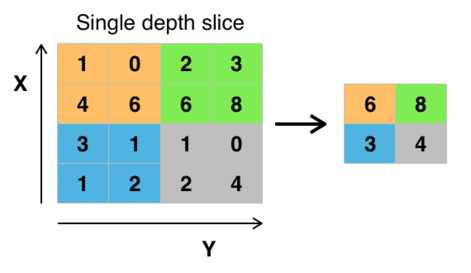

Image Source: Wikipedia

#### RELU layer:

This is the rectified Linear unit. This is to remove negative values from the output of the maxpooling layer. The negative values are set to zero.

These are the basic layers in the hidden layers. You can have many units of [convolution layer-max pooling layer- RELU layer]. After the final RELU layer we have the fully connected Layer.

#### Fully Connected Layer:

Fully connected layer is connected to all the activations of all the previous layer. If we train the network to identify '**N**' objects, the fully connected layer will have **N** outlets. i.e., For identifying 4 objects we need 4 outlets in fullyconnected layer. The matrix obtained from the previous stages is converted into a vector.

#### LOSS Layer:

This is sort of feed back function from the output to input, whenever there is wrong identification of the object. Softmax function is used for identifying N different objects.

#### Classification Layer:

The finaly layer is the classification layer. This will map the input to a specific output.

#### Making a CNN from Scratch:

We can make a CNN from scratch. We need to have an input layer, followed by multiples of (convolution-max pooling-RELU), followed by fully connected layer, softmax layer and finally classification layer. 

We need to input all the inputs along with their labels and it can be a tedious process. 

We can also use allready pretrained networks like ALEXNet, GoogleNet etc., In this tutorial we are going to use ALEXnet to classify digits. AlexNet is mainly for classifying images. 

The model has five convolutional layers in the feature extraction  part of the model and three fully connected layers in the classifier  part of the model.

Input images were fixed to the size 224×224 with three color channels. So yes if your input images are gray scale or smaller or bigger you may have to resize and change the picture format to match the requirement of AlexNet.

So for resizing a image or changing the input to 224x224x3 let us write a function. We will invoke this function if necessary.

## let us begin

We have stored images of all numbers from 0 to 1 in different folders named as 0,1, etc. The folders names are the labels or the class. I have stored all of the sub folders inside the main folder training set. 

Create a variable called imds ( it can be any name). I am giving the folder name and asking it to IncludeSubFolders by saying true. The label sources are the folder names. My folder name is trainingSet where the data is stored. Within this folder the various digits are stored in different in various folders. That is all '1' stored in folder name '1', '0' in '0' folder etc. There are a total of 10 subfolders with in the main folder named trainingSet. 

clc;
clear;
imds=imageDatastore('trainingSet','IncludeSubfolders', true,...
      'LabelSource','foldernames');

The total number of images and classes are displayed as below.

no_of_images=numel(imds.Files);
No_of_class=numel(categories(imds.Labels));

Now we split the data for traaining and testing.

[Traindata,Testdata]= splitEachLabel(imds,0.9);
Traindata.ReadFcn=@convert;

Next we load Alexnet.

Required Matlab tool Box: **Deep Learning Toolbox Model for AlexNet Network **

For all pretrained net we will have to download the respective toolbox model from Mathworks. This is very easy procedure search for AlexNet in add on tab in Matlab home menu.

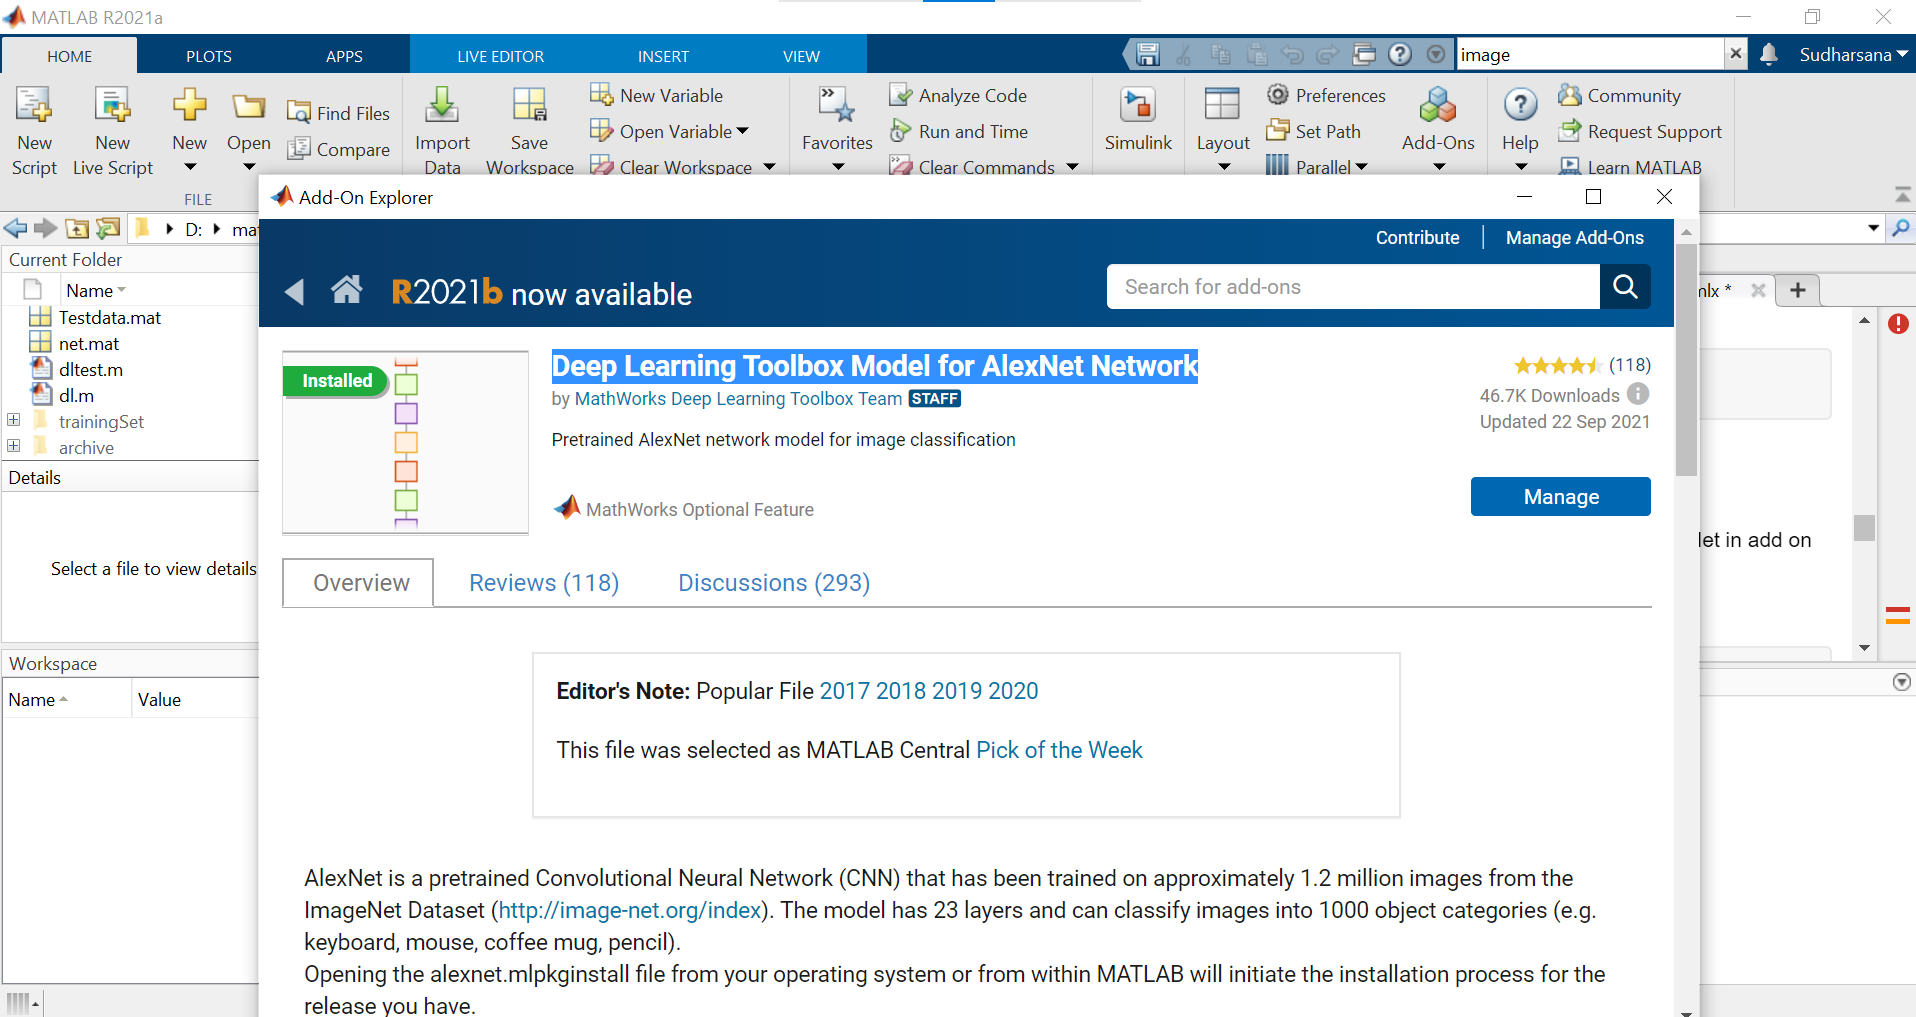

net = alexnet();
Layers=net.Layers;
Layers(23)=fullyConnectedLayer(No_of_class);
Layers(25)=classificationLayer();

Here we load the alexnet. Layer (23) is the fully connected layer, which in this case will be 10 because we need to find 10 digits. Layer(25) is the classification  layer. The other layers are already inbuilt in alexnet. So we dont have to specify them. Alexnet is designed to identify 1000 different objects. Here we use them to identify 10.

 options = trainingOptions('sgdm', ...
            'Plots', 'training-progress', ...
            'LearnRateSchedule', 'piecewise', ...
            'LearnRateDropFactor', 0.2, ...
            'LearnRateDropPeriod', 5, ...
            'MiniBatchSize', 500);
        options.InitialLearnRate=0.001;
        options.MaxEpochs=50;
        %options.MiniBatchSeize=150


We set the options we require to train the network. The three solvers are used to train the network. 

'sgdm'    -   Stochastic gradient descent with momentum.

'adam'    -   Adaptive moment estimation (ADAM).

'rmsprop' -   Root mean square propagation (RMSProp).

Rest all are other paramters needed to tune according to the needs of the problem.

Finally we train the network and save it. This will take some time.

This will really take a long time in MLX. Store them as a m file and run, it might be faster. Minimum 8GB RAM is required. You can stop the training when the accuracy reaches close to 100%. 

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:28 |       13.60% |       2.4147 |          0.0010 |
|       1 |          50 |       00:18:36 |       91.80% |       0.3556 |          0.0010 |
|       2 |         100 |       00:37:11 |       95.80% |       0.1242 |          0.0010 |
|       2 |         150 |       00:55:20 |       97.60% |       0.0963 |          0.0010 |
|       3 |         200 |       01:20:02 |       97.60% |       0.0747 |          0.0010 |
|       4 |         250 |       01:43:07 |       98.40% |       0.0679 |          0.0010 |
|       4 |         300 |  

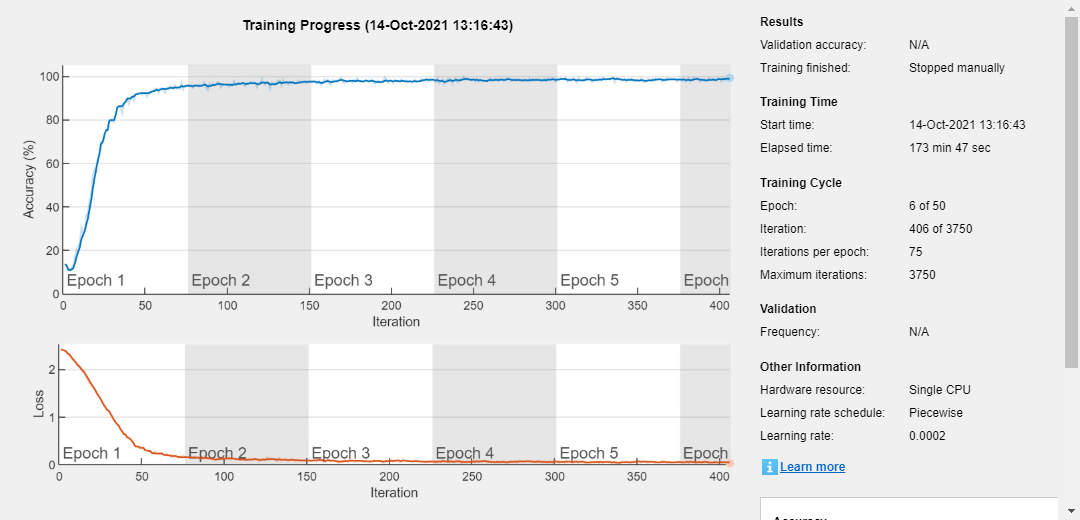

   [Alexnet_digit_classification,info]=trainNetwork(Traindata,Layers,options);

   save Alexnet_digit_classification Alexnet_digit_classification


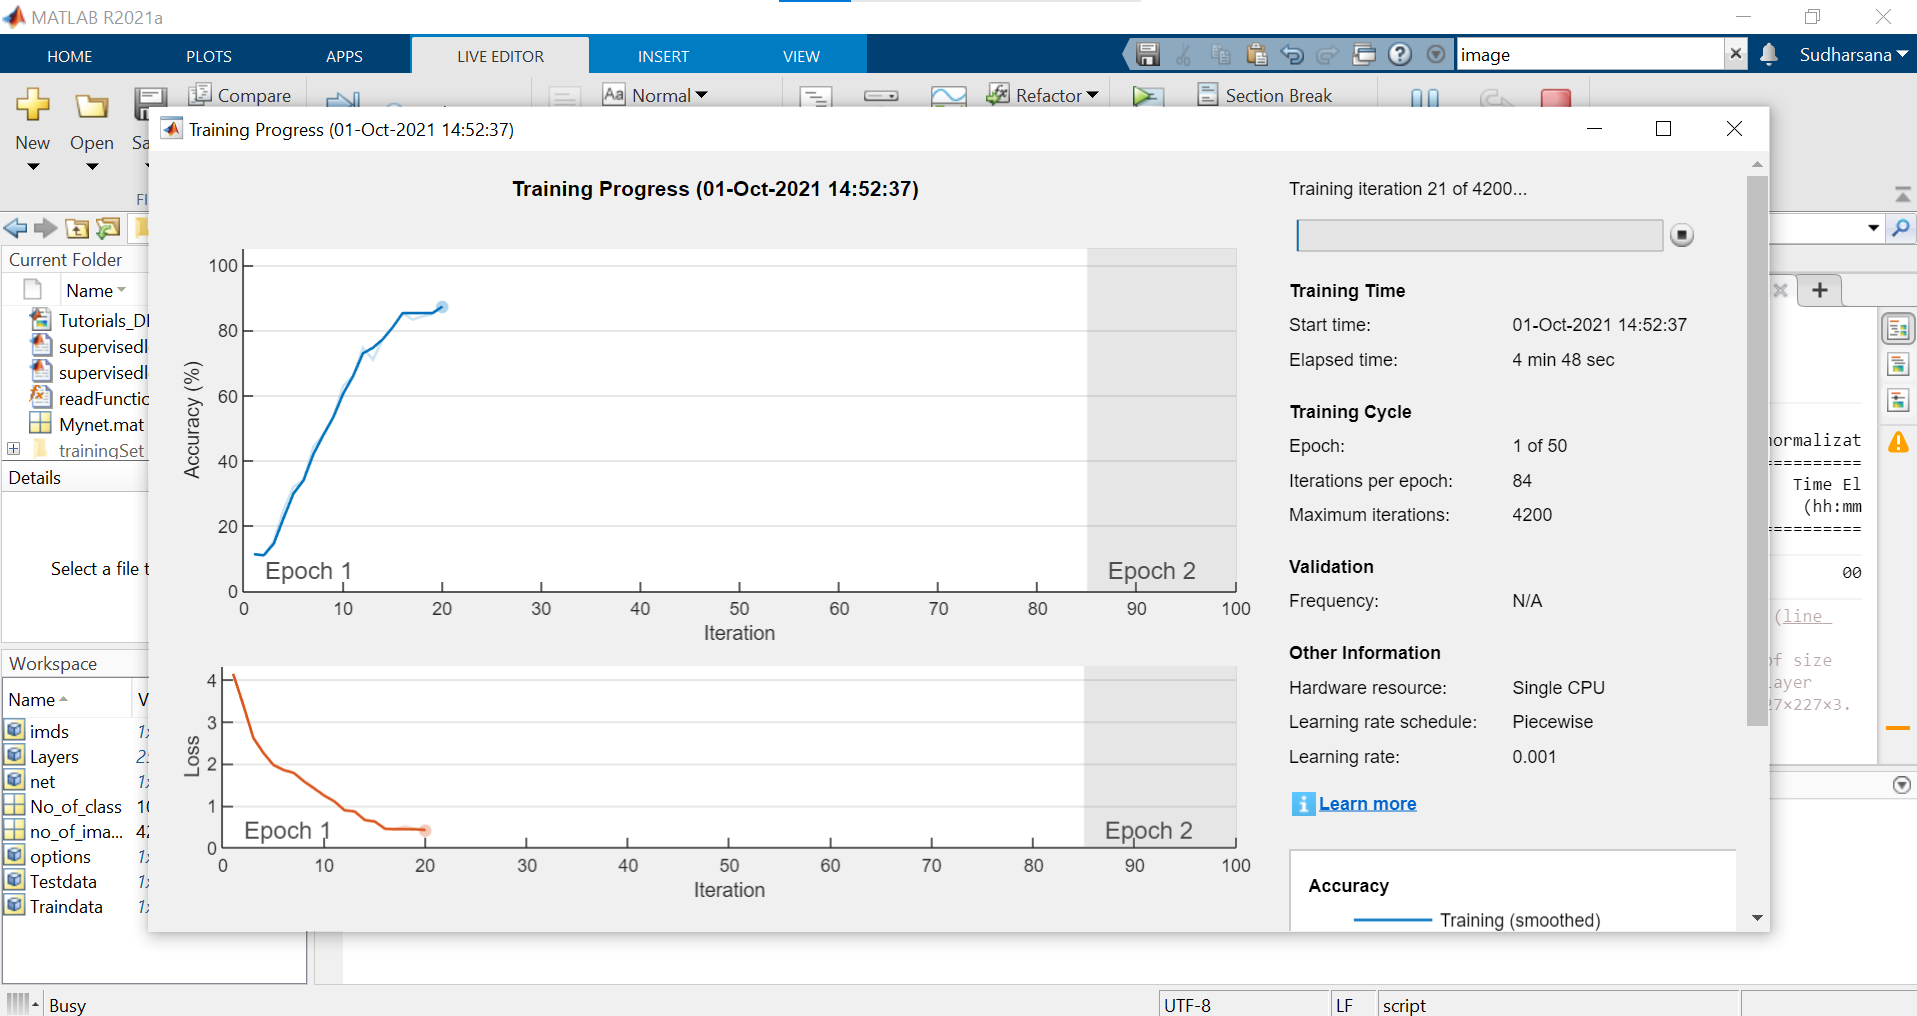

Let us now clear our matlab workspace for fresh detection.

   clc;
   clear;
      

   clc;
load Alexnet_digit_classification.mat




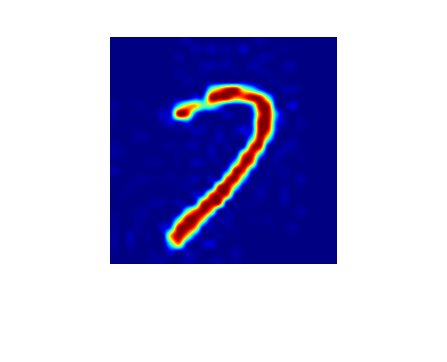

     7 



[filename,pathname]=uigetfile('*.*'); % When the file explorer opens select all files at bottom.
    if isequal(filename,0)|| isequal(pathname,0)
    wardlg("user")
    else
        a=imread([pathname,filename]);
        a=imresize(a,[227 227]);
        cmap = jet(256); % Or whatever one you want. Another way to convert an image to color.
        A = ind2rgb(a, cmap); % we can use the convert function also.
        imshow(A)
        class=classify(Alexnet_digit_classification,A);
        disp(class)
    end

Error using imread>parse_inputs (line 504)
The file name or URL argument must be a character vector or string scalar.

Error in imread (line 342)
[source, fmt_s, extraArgs, was_cached_fmt_used] = parse_inputs(cached_fmt, varargin{:});

Error in 

function [A] = convert(imds)
a=imresize(imds,[227 227]);
cmap = jet(256); 
A = ind2rgb(a, cmap);
end



